Cleaning console

clear;
clc;

Setting file system variables

home = "/Users/edwinjoseph/Projects/leather-species-identification/";

source = strcat(home,"data/images/Train_grey/");

if not(isfolder(source))
   error(strcat("image source folder does not exist: ", source));
   exit(1);
end

target = strcat(home,"data/features/LBP_segregated/Train_grey/");
if not(isfolder(target))
   mkdir(target);
end

files = dir(source);
files = files(~ismember({files.name},{'.' '..'}));

for i=1:length(files)
    I = imread(strcat(source,files(i).name));

Detect SIFT features in the image.

    points = detectSIFTFeatures(I);

Display the results

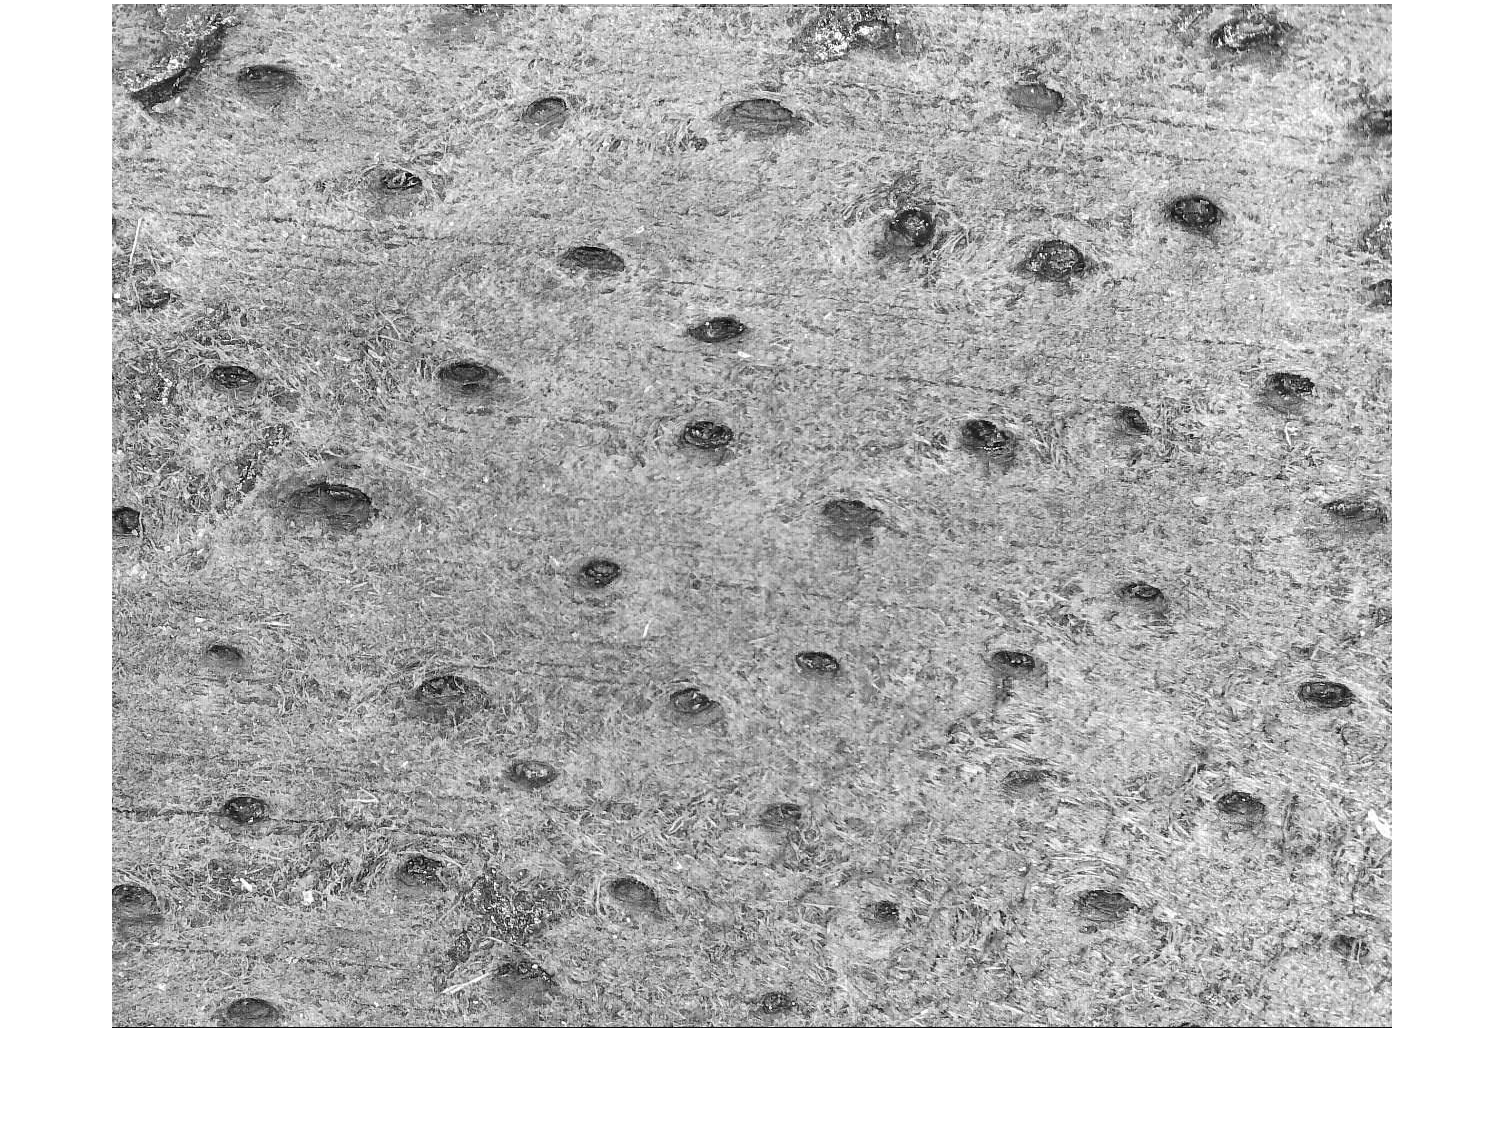

Unrecognized function or variable 'detectSIFTFeatures'.

    imshow(I);
    hold on;
    % plot(points)
    top100 = plot(points.selectStrongest(100))
    [filepath,name,~] = fileparts(files(i).name);
    saveas(top100, strcat(filepath,name,"1e2.jpg"));
    hold off;

    imshow(I);
    hold on;
    % plot(points)
    top1000 = plot(points.selectStrongest(1000))
    [filepath,name,~] = fileparts(files(i).name);
    saveas(top1000, strcat(filepath,name,"1e3.jpg"));
    hold off;

    imshow(I);
    hold on;
    % plot(points)
    top10000 = plot(points.selectStrongest(10000))
    [filepath,name,~] = fileparts(files(i).name);
    saveas(top10000, strcat(filepath,name,"1e4.jpg"));
    hold off;
end